# **PHYS 4030: Project**

**Name: **Johannes Irnawan

# Project Topic: Chaos in Three Body Problem

### **Hypothesis** 

Is it possible for a three body system to have a chaotic behaviour without colliding or ejecting any body?

### How can the hypothesis be proven?

The hypothesis is easily proven by finding a system that shows a chaotic behaviour but does not collide nor eject a body. Hence, there are three conditions for this hypothesis to be proven:

- Shows chaotic behaviour

- No collision

- Does not eject a body

#### Chaotic Behavior

A chaotic behaviour arises when a small changes in initial condition of a system yield a completely different outcomes. In the case of the three body problem, a chaotic behaviour can be shown by changing a variable of a single body. Hence, the chaotic behaviour of the three body problem can be shown by just changing a single variable.

#### No Collision

A collision happens when two or more objects occupies the same space at any time in the simulation. In the simulation, if collision physics is not scripted into the simulation, the equation of motion blows up when there is a collision. 

#### No Ejection

An ejection of an object in a system happens when an object moves away from the system such that its velocity is higher than the escape velocity. Visually, an ejection can be seen when an object moves away from the center of mass towards infinity.

### Prediction

For this system, it is **not** possible for a three body system to have a chaotic behaviour without colliding or ejecting any body.

# Specific Case for Hypothesis

The hypothesis has three conditions to be fulfilled. For this project, the hypothesis will only be checked against specific cases:

- 2-Dimensional three body system

- Two of the three masses are equal: $M_1 \not= M_2 =M_3$

- Only one varying initial condition: $M_2$

- Bounded to a ratio of masses: $M_2 \approx RM_1$where $R=0\ldotp 1$

- Bounded to a small change in initial mass: $\Delta M<<R$ 

- Equilatelar triangular system, the initial positions of the objects make up an equilateral triangle shape.

- Bounded to a finite time range: $t\in \left\lbrack 0,t_{\textrm{end}} \right\rbrack$ where $t_{\textrm{end}} =50\;\textrm{years}$

The initial conditions that will be checked:

- Velocity for mass 1: $\overrightarrow{v_1 } =\left(-{10}^{-7} ,\;0\right)\frac{\textrm{AU}}{s}$

- Velocity for mass 2: $\overrightarrow{v_2 } =\left(\frac{{10}^{-7} }{2},\;-\frac{{\sqrt{3}*10}^{-7} }{2}\right)\;\frac{\textrm{AU}}{s}$

- Velocity for mass 3: $\overrightarrow{v_3 } =\left(\frac{{10}^{-7} }{2},\;\frac{\sqrt{3}*{10}^{-7} }{2}\right)\;\frac{\textrm{AU}}{s}$

- Position for mass 1: $\overrightarrow{r_1 } =\left(0,\;5\right)\;\textrm{AU}$

- Position for mass 2: $\overrightarrow{r_2 } =\left(-\frac{5\sqrt{3}}{2},-\frac{5}{2}\right)\;\textrm{AU}$

- Position for mass 3: $\overrightarrow{r_3 } =\left(\frac{5\sqrt{3}}{2},-\frac{5}{2}\right)\;\textrm{AU}$

# Techniques to Prove the Hypothesis

#### Techniques that will be used:

- Pathlines that shows the motions of the bodies and the path of the motions.

- Position graph of each body (i.e. position in x vs time).

#### How can the techniques prove the hypothesis?

- **Pathlines:** Helps visualize the motions of the system.

- **Postion Graph:** For many initial conditions, the position graph of each body can be superimposed. This can show the chaotic behaviour of the system. The position graph can also shows ejection if one of the object is moving further away from the center of mass without going back towards the other bodies.

- To note, the collision physics will not be coded. Therefore, the only way to show collisions is when the equation of motion blows up at a certain time t. When this happens, the position graph will only show the motions of the system from initial time $t=0$ to the time of collision $t\not= t_{\textrm{end}}$.

# Setting Up The Codes

#### Setting up the parameters

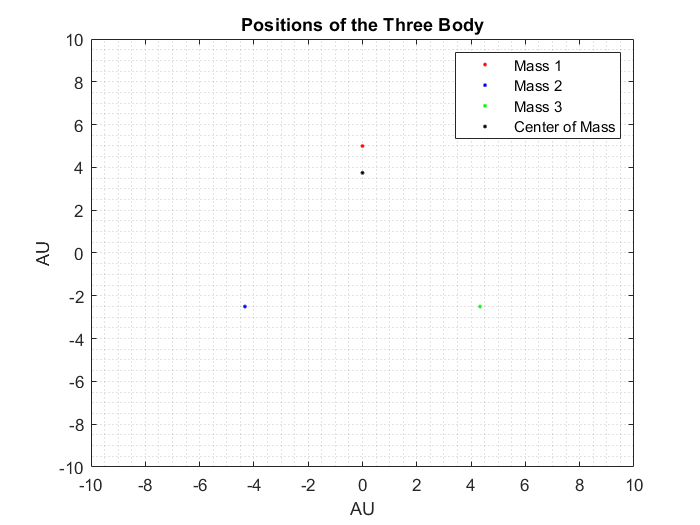

% Clearing the memory
clc; clear; clf;

% Setting up the parameters
G = 6.674E-11;          % Gravitational constant (m3 kg-1 s-2)
M_solar = 1.988E30;     % Solar mass (kg)
AU2m = 1.495978707E11;  % AU in terms of m
yr2s = 60*60*24*365.25; % Seconds in a year

% Time parameter:
% In years:
time.yrs = [0 50];
% In seconds:
time.s = time.yrs*yr2s;

% Mass parameters:
M1 = 30*M_solar;         % Mass in solar masses
Ratio = [0.0996 0.0997 0.0998 0.0999 0.1 0.1001 0.1002 0.1003 0.1004 0.1005];
M2 = Ratio*M1;

% Initial velocities for object 1, 2, and 3:
% In AU/s:
initial.ausvel_x = 1E-7*[-1 1/2 1/2];
initial.ausvel_y = 1E-7*[0 -sqrt(3)/2 sqrt(3)/2];
% In m/s:
initial.msvel_x = initial.ausvel_x*AU2m;
initial.msvel_y = initial.ausvel_y*AU2m;

% Initial positions for object 1, 2, and 3:
% In AU:
initial.aupos_x = 5*[0 -sqrt(3)/2 sqrt(3)/2];
initial.aupos_y = 5*[1 -1/2 -1/2];
% in m:
initial.mpos_x = initial.aupos_x*AU2m;
initial.mpos_y = initial.aupos_y*AU2m;

% Showing the positions of the masses for M2 = 0.1M1:
[CoM.x,CoM.y] = center_of_mass_p([M1 M2(5) M2(5)],...
    [initial.aupos_x' initial.aupos_y']);
clf; figure();
plot(initial.aupos_x(1),initial.aupos_y(1),'r.',initial.aupos_x(2),...
    initial.aupos_y(2),'b.',initial.aupos_x(3),initial.aupos_y(3),'g.',...
    CoM.x,CoM.y,'k.')
grid minor, xlabel('AU'), ylabel('AU')
title('Positions of the Three Body')
legend('Mass 1','Mass 2', 'Mass 3','Center of Mass')
axis([-10 10 -10 10]);

#### Setting up equations of motions

The equation of motion for this problem is set as the function "three_body_system.m". The function includes ODEs for velocity and acceleration and uses Newtonian equations of motion:


$$\dot{\overrightarrow{r_1 } } =\frac{d}{dt}\overrightarrow{r_1 } =\left(\dot{x_1 } ,\dot{y_1 } ,\dot{z_1 } \right)$$



$$\dot{\overrightarrow{r_2 } } =\frac{d}{dt}\overrightarrow{r_2 } =\left(\dot{x_2 } ,\dot{y_2 } ,\dot{z_2 } \right)$$



$$\dot{\overrightarrow{r_3 } } =\frac{d}{dt}\overrightarrow{r_3 } =\left(\dot{x_3 } ,\dot{y_3 } ,\dot{z_3 } \right)$$



$$\ddot{\overrightarrow{r_1 } } =-{GM}_2 \frac{\overrightarrow{\;r_1 } -\overrightarrow{\;r_2 } }{\left|\overrightarrow{\;r_1 } -\overrightarrow{\;r_2 } {\left|\right.}^3 \right.}-{GM}_3 \frac{\overrightarrow{\;r_1 } -\overrightarrow{\;r_3 } }{\left|\overrightarrow{\;r_1 } -\overrightarrow{\;r_3 } {\left|\right.}^3 \right.}$$



$$\ddot{\overrightarrow{r_2 } } =-{GM}_3 \frac{\overrightarrow{\;r_2 } -\overrightarrow{\;r_3 } }{\left|\overrightarrow{\;r_2 } -\overrightarrow{\;r_3 } {\left|\right.}^3 \right.}-{GM}_1 \frac{\overrightarrow{\;r_2 } -\overrightarrow{\;r_1 } }{\left|\overrightarrow{\;r_2 } -\overrightarrow{\;r_1 } {\left|\right.}^3 \right.}$$



$$\ddot{\overrightarrow{r_3 } } =-{GM}_1 \frac{\overrightarrow{\;r_3 } -\overrightarrow{\;r_1 } }{\left|\overrightarrow{\;r_3 } -\overrightarrow{\;r_1 } {\left|\right.}^3 \right.}-{GM}_2 \frac{\overrightarrow{\;r_3 } -\overrightarrow{\;r_2 } }{\left|\overrightarrow{\;r_3 } -\overrightarrow{\;r_2 } {\left|\right.}^3 \right.}$$


# Testing

#### Set up

For testing purposes, the initial conditions will be fixed (i.e. using only one mass 2). The mass that will be used is $M_2 =0\ldotp 1M_1$:

% Mass Parameter:
n = 5;      % for M2 = k*M1, M2(n) = k(n)*M1
% Testing:
test.ODE = @(t,R) three_body_system(t,R,G,[M1 M2(n) M2(n)]);
test.ini_cond = ... Initial conditions for positions:
    [initial.mpos_x(1) initial.mpos_y(1) ...
    initial.mpos_x(2) initial.mpos_y(2) ...
    initial.mpos_x(3) initial.mpos_y(3) ...
    ... Initial conditions for velocities:
    initial.msvel_x(1) initial.msvel_y(1) ...
    initial.msvel_x(2) initial.msvel_y(2) ...
    initial.msvel_x(3) initial.msvel_y(3)];
% Evaluating Positions and velocities using ODE45:
[test.t,test.R] = ode45(test.ODE,time.s,test.ini_cond);

test.R = test.R/AU2m;

#### Showing pathlines of the masses

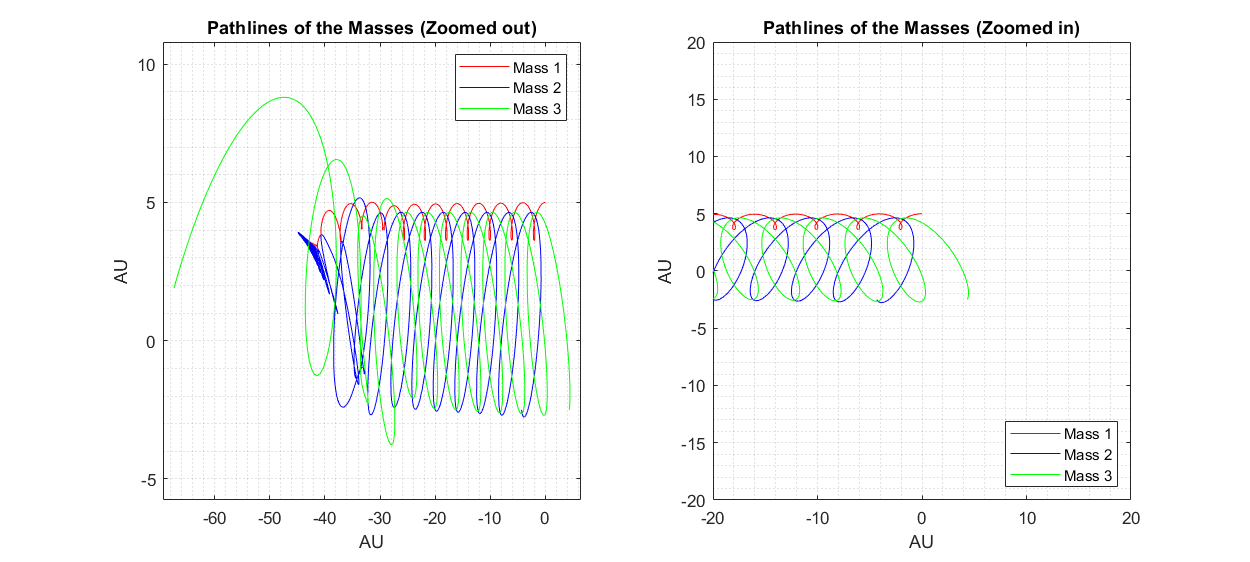

% Pathlines of the objects:
% Axis Boundaries:
xmin = min([test.R(:,1);test.R(:,3);test.R(:,5)]);
xmax = max([test.R(:,1);test.R(:,3);test.R(:,5)]);
ymin = min([test.R(:,2);test.R(:,4);test.R(:,6)]);
ymax = max([test.R(:,2);test.R(:,4);test.R(:,6)]);
% Plotting pathlines:
clf; figure();
figure1 = figure('Position',[100,100,1000,450]);
subplot(1,2,1)
plot(test.R(:,1),test.R(:,2),'r',test.R(:,3),test.R(:,4),'b',...
    test.R(:,5),test.R(:,6),'g')
grid minor, xlabel('AU'), ylabel('AU')
legend('Mass 1','Mass 2','Mass 3','Location','Best')
title('Pathlines of the Masses (Zoomed out)')
axis([xmin-2 xmax+2 ymin-2 ymax+2])
subplot(1,2,2)
plot(test.R(:,1),test.R(:,2),'r',test.R(:,3),test.R(:,4),'b',...
    test.R(:,5),test.R(:,6),'g')
grid minor, xlabel('AU'), ylabel('AU')
legend('Mass 1','Mass 2','Mass 3','Location','Best')
title('Pathlines of the Masses (Zoomed in)')
axis([-20 20 -20 20])

#### Plotting Position vs Time

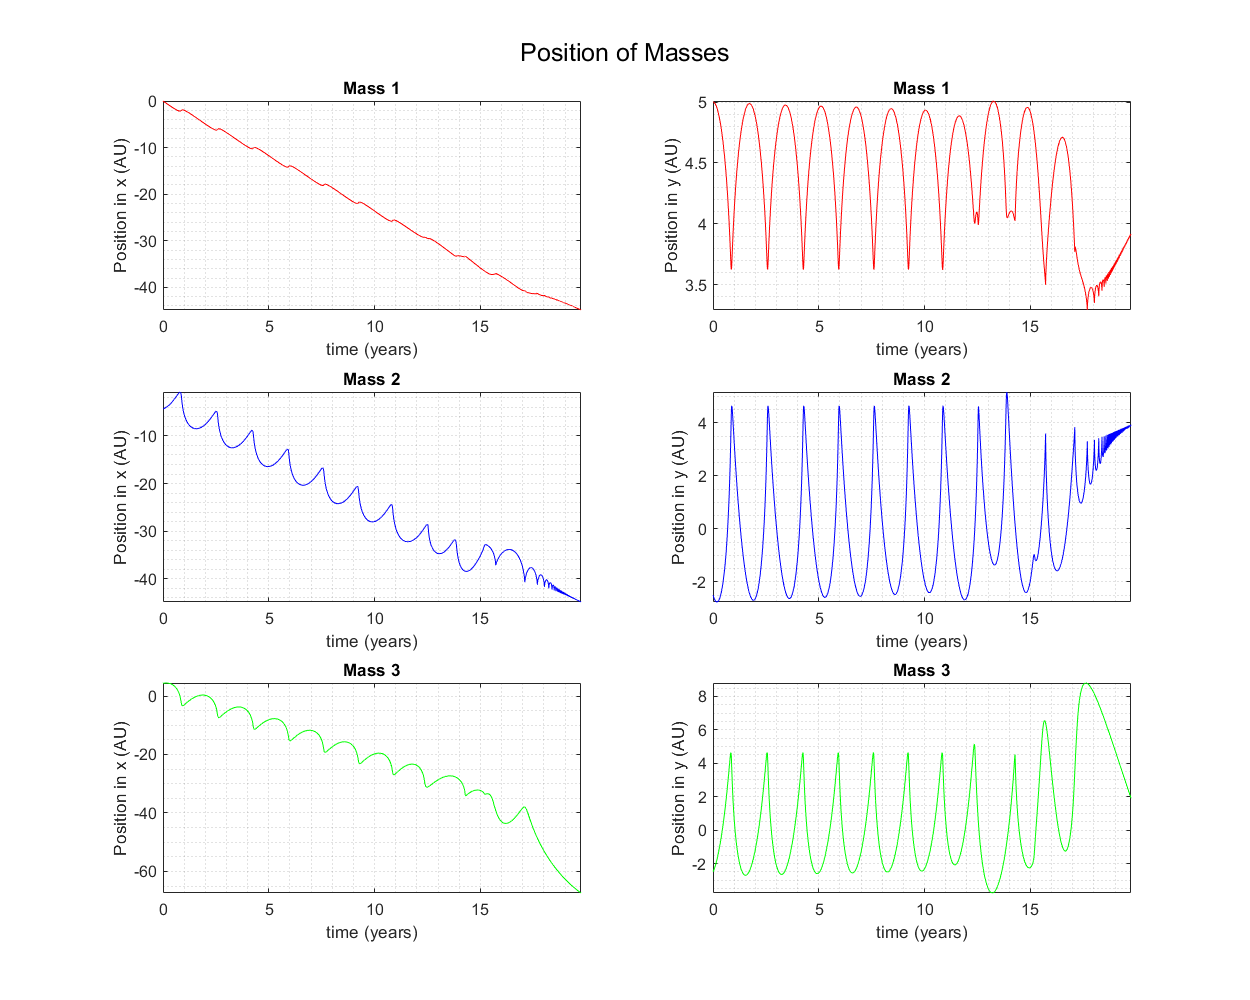

% Plotting:
clf; figure();
figure2 = figure('Position',[100,100,1000,800]);
for l = 1:6
    subplot(3,2,l)
    if ceil(l/2) == 1
        colour = 'r';
        Mass = 'Mass 1';
    elseif ceil(l/2) == 2
        colour = 'b';
        Mass = 'Mass 2';
    else
        colour = 'g';
        Mass = 'Mass 3';
    end
    plot(test.t/yr2s,test.R(:,l),colour)
    grid minor, xlabel('time (years)')
    title(Mass);
    if ceil(l/2) ~= floor(l/2)
        ylabel('Position in x (AU)');
    else
        ylabel('Position in y (AU)');
    end
    axis([test.t(1)/yr2s test.t(end)/yr2s min(test.R(:,l)) max(test.R(:,l))]);
end
sgtitle('Position of Masses')

# Plotting the Simulation

In this part, the positions of each masses will be plotted with varying $M_2$. 

To note from the previous test: 

- When there is a collision between two masses, their distance goes to zero. In this case, the ODE solver blows up and it stops calculating. Hence, the time domain for a collisional system is $t\in \left\lbrack 0,t_{\textrm{collision}} \right\rbrack$. If $t_{\textrm{collision}} <t_{\textrm{end}}$, then the hypothesis is proven wrong.

#### Simulation: Pathlines

clf; figure()
figure1 = figure('Position',[100,100,2500,1200]);
for n = 1:length(M2)
    sim.ODE = @(t,R) three_body_system(t,R,G,[M1 M2(n) M2(n)]);
    sim.ini_cond = ... Initial conditions for positions:
        [initial.mpos_x(1) initial.mpos_y(1) ...
        initial.mpos_x(2) initial.mpos_y(2) ...
        initial.mpos_x(3) initial.mpos_y(3) ...
        ... Initial conditions for velocities:
        initial.msvel_x(1) initial.msvel_y(1) ...
        initial.msvel_x(2) initial.msvel_y(2) ...
        initial.msvel_x(3) initial.msvel_y(3)];
    % Evaluating Positions and velocities using ODE45:
    sim.t = []; sim.R = [];
    [sim.t,sim.R] = ode45(sim.ODE,time.s,sim.ini_cond);
    sim.R = sim.R/AU2m;
    
    % Plotting Pathlines
    subplot(2,5,n)
    plot(sim.R(:,1),sim.R(:,2),'r',sim.R(:,3),sim.R(:,4),'b',...
        sim.R(:,5),sim.R(:,6),'g')
    grid minor, xlabel('AU'), ylabel('AU')
    legend('Mass 1','Mass 2','Mass 3','Location','Best')
    title(['Pathlines: M_2 = ',num2str(Ratio(n)),' M_1'])
end

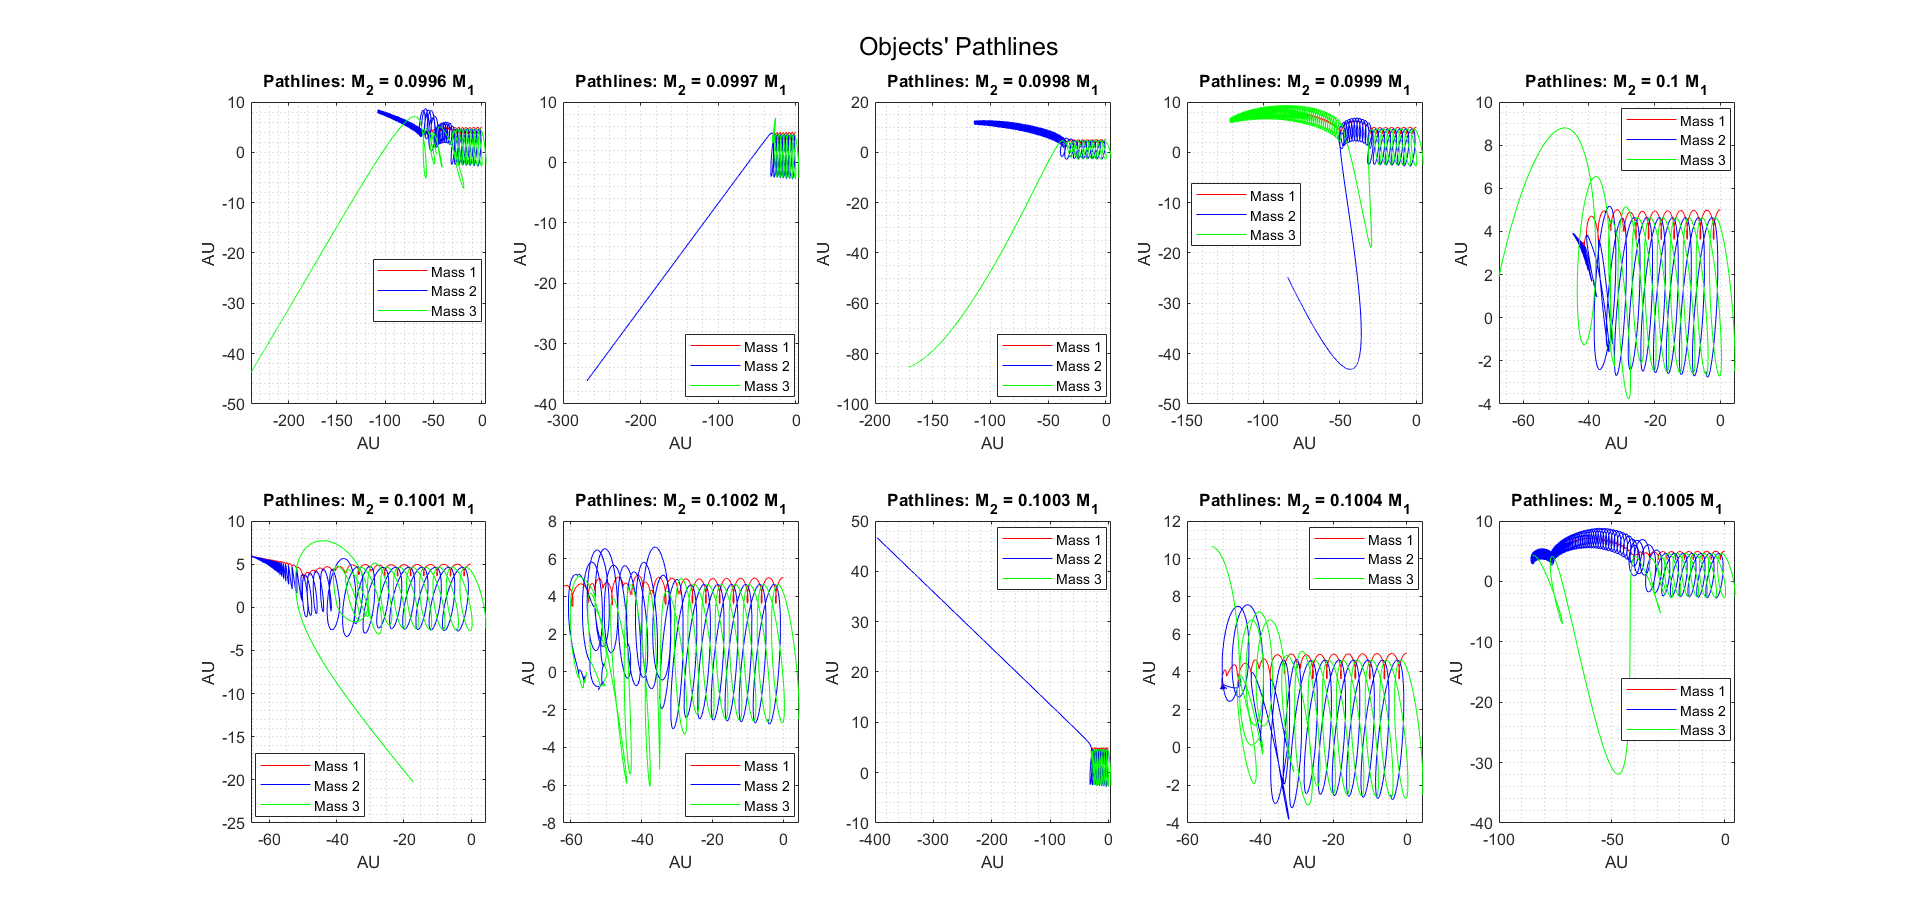

sgtitle("Objects' Pathlines")

From the pathlines shown, some systems ejects one object in the given time domain.

#### Simulation: Position vs Time

clf; figure()
figure1 = figure('Position',[100,100,1000,800]);
ejection_coeff = [];
for n = 1:length(M2)
    sim.ODE = @(t,R) three_body_system(t,R,G,[M1 M2(n) M2(n)]);
    sim.ini_cond = ... Initial conditions for positions:
        [initial.mpos_x(1) initial.mpos_y(1) ...
        initial.mpos_x(2) initial.mpos_y(2) ...
        initial.mpos_x(3) initial.mpos_y(3) ...
        ... Initial conditions for velocities:
        initial.msvel_x(1) initial.msvel_y(1) ...
        initial.msvel_x(2) initial.msvel_y(2) ...
        initial.msvel_x(3) initial.msvel_y(3)];
    % Evaluating Positions and velocities using ODE45:
    sim.t = []; sim.R = [];
    [sim.t,sim.R] = ode45(sim.ODE,time.s,sim.ini_cond);
    sim.R = sim.R/AU2m;
    % Saving the final time for simulation
    final.time(n) = sim.t(end)/yr2s;
    
    % Ejection Status
    for l = 1:3
        CoM.x = [];
        CoM.y = [];
        pos.x = sim.R(end,2*l-1);
        pos.y = sim.R(end,2*l);
        vel.x = sim.R(end,5+2*l);
        vel.y = sim.R(end,6+2*l);
        vel.total = sqrt(vel.x^2 + vel.y^2);
        if l == 1
            [CoM.x,CoM.y] = center_of_mass_p([M2(n) M2(n)],...
                [sim.R(end,9),sim.R(end,10);sim.R(end,11),sim.R(end,12);]);
            vel.total = sqrt((vel.x-CoM.x)^2 + (vel.y-CoM.y)^2);
            ejection_coeff(n) = 1;
            [CoM.x,CoM.y] = center_of_mass_p([M2(n) M2(n)],...
                [sim.R(end,3),sim.R(end,4);sim.R(end,5),sim.R(end,6);]);
            escape_vel = sqrt(4*G*M2(n)/sqrt(CoM.x^2 + CoM.y^2));
        elseif l == 2
            [CoM.x,CoM.y] = center_of_mass_p([M1 M2(n)],...
                [sim.R(end,7),sim.R(end,8);sim.R(end,11),sim.R(end,12);]);
            vel.total = sqrt((vel.x-CoM.x)^2 + (vel.y-CoM.y)^2);
            [CoM.x,CoM.y] = center_of_mass_p([M1 M2(n)],...
                [sim.R(end,1),sim.R(end,2);sim.R(end,5),sim.R(end,6);]);
            escape_vel = sqrt(2*G*M1*M2(n)/sqrt(CoM.x^2 + CoM.y^2));
        else
            [CoM.x,CoM.y] = center_of_mass_p([M1 M2(n)],...
                [sim.R(end,7),sim.R(end,8);sim.R(end,9),sim.R(end,10);]);
            vel.total = sqrt((vel.x-CoM.x)^2 + (vel.y-CoM.y)^2);
            [CoM.x,CoM.y] = center_of_mass_p([M1 M2(n)],...
                [sim.R(end,1),sim.R(end,2);sim.R(end,3),sim.R(end,4);]);
            escape_vel = sqrt(2*G*M1*M2(n)/sqrt(CoM.x^2 + CoM.y^2));
        end
        if ejection_coeff(n) == 1
            if vel.total >= escape_vel
                ejection_coeff(n) = 2;
            end
        end
    end
    % Plotting Position vs Time
    for l = 1:6
        subplot(3,2,l)
        if ceil(l/2) == 1
            Mass = 'Mass 1';
        elseif ceil(l/2) == 2
            Mass = 'Mass 2';
        else
            Mass = 'Mass 3';
        end
        plot(sim.t/yr2s,sim.R(:,l))
        xlabel('time (years)')
        title(Mass);
        if ceil(l/2) ~= floor(l/2)
            ylabel('Position in x (AU)');
        else
            ylabel('Position in y (AU)');
        end
        hold on
    end
end

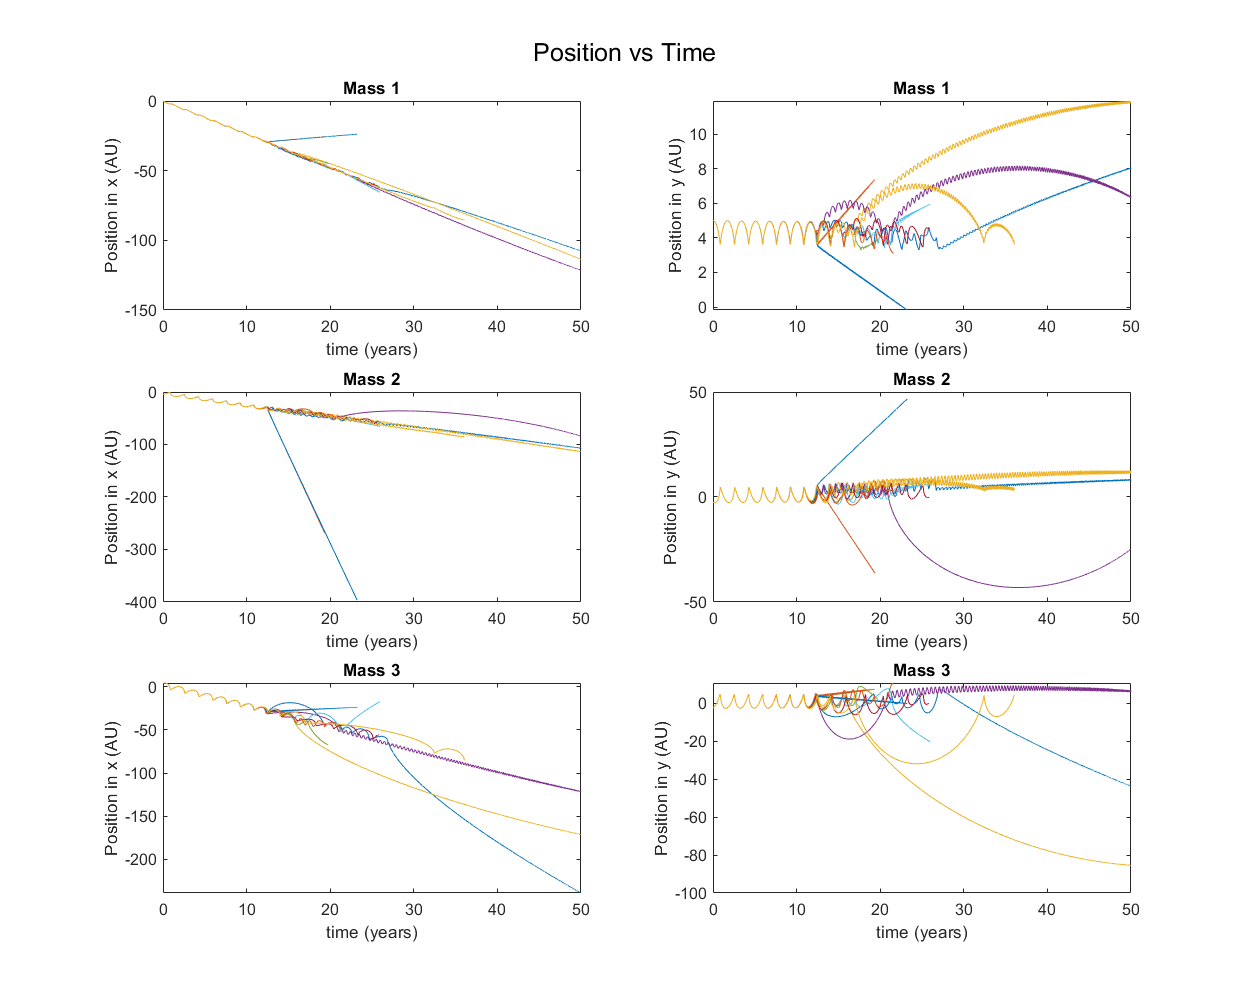

sgtitle('Position vs Time')

From the position graphs shown, most systems have collisions.

#### Status Conclusion

% Ejection and Collision Status
status = [];
for n = 1:length(Ratio)
    status.Ratio(n) = Ratio(n);
end
status.Ratio = status.Ratio';
status.Ejection = strings(10,1);
status.Collision = strings(10,1);
for n = 1:length(final.time)
    if final.time(n) < time.yrs(end)
        status.Collision(n) = "Collisional";
    else
        status.Collision(n) = "Non Collisional";
    end
    if ejection_coeff(n) == 1
        status.Ejection(n) = "No Ejection";
    else
        status.Ejection(n) = "Ejection";
    end
end
% Status Table
struct2table(status)

ans = 10×3 table
    Ratio       Ejection           Collision    
    ______    _____________    _________________

    0.0996    "No Ejection"    "Non Collisional"
    0.0997    "No Ejection"    "Collisional"    
    0.0998    "No Ejection"    "Non Collisional"
    0.0999    "No Ejection"    "Non Collisional"
       0.1    "No Ejection"    "Collisional"    
    0.1001    "No Ejection"    "Collisional"    
    0.1002    "No Ejection"    "Collisional"    
    0.1003    "No Ejection"    "Collisional"    
    0.1004    "No Ejection"    "Collisional"    
    0.1005    "No Ejection"    "Collisional"    


# Conclusion

The system's status shows that one of the conditions is not satisfied, which is non-collisional. Therefore, for this system, the hypothesis is proven to be not true.

This has a strong emphasize on "this system". There are other systems where the hypothesis is proven to be true, and thus it is true in general. One such system is a zero angular momentum solution found by Cris Moore, which includes three equal masses moving in a figure 8 orbit.